% Package orientation: Dedicated held-out test for a separately trained SPSA network.

% TEST_SPSA_GPU_implementation_classification_BC.mlx
% Load SPSA-trained BC networks and evaluate the held-out split with the
% same standard test, plotting, diagnostics, and publication-data export
% used by the main GPU test script. This script does not train.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved SPSA Network ----------------
% The SPSA runner currently creates seed 1 by default. Use [1 2 3] after
% training all three SPSA seeds to obtain multi-seed release statistics.
test_seeds = [1];
diagnostic_seed_index = 1;
test_backend = 'gpu';
[model_files, model_file] = snn_resolve_spsa_model_files( ...
    repo_root, 'classification_BC', test_seeds, diagnostic_seed_index);

[SPSA continuation] seed 1: testing the terminal model after 50000 total epochs (phase boundaries after epoch(s): 5000).


save_diagnostic_files = false;
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', 'classification_BC_spsa_test_gpu_primary');
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end

%% ---------------- Evaluation Overrides ----------------
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file;
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
result = snn_primary_api('test_static', 'classification', test_backend, opts);

[SEED AUDIT] Single seed tested; no pairwise network-difference check required.


Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\classification_BC_lowrank_SPSA_GPU_primary_seed001_continued_45000epochs_gpu_test_analysis_20260721_144949_793.mat


fprintf('Tested SPSA-trained BC network(s) for seed(s) [%s] with the GPU test backend.\n', num2str(test_seeds));

Tested SPSA-trained BC network(s) for seed(s) [1] with the GPU test backend.


    Seed     Loss      AccuracyPercent
    ____    _______    _______________

     1      0.23642        93.913     



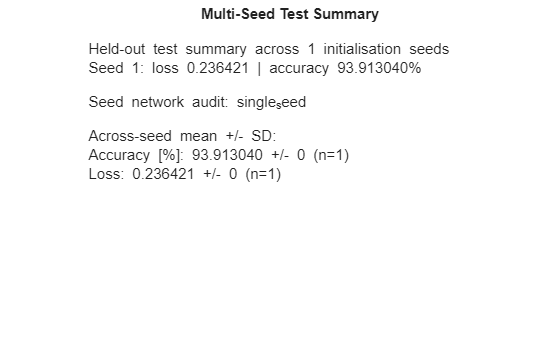

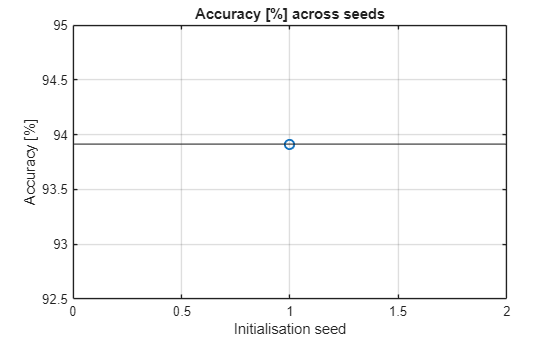

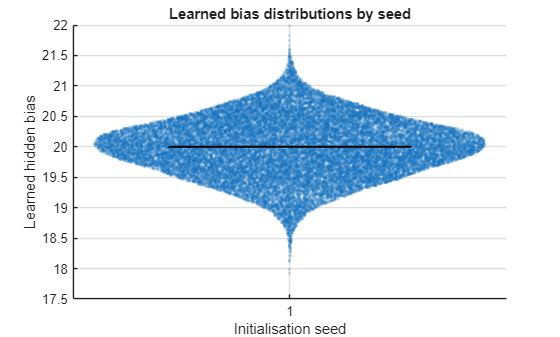

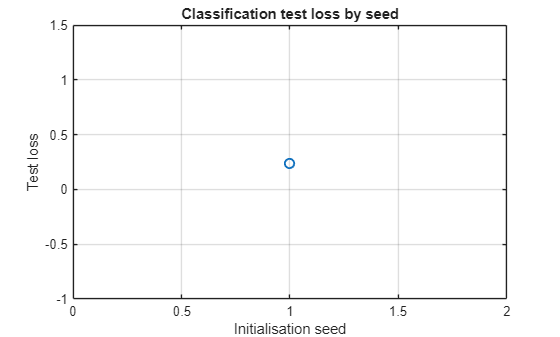

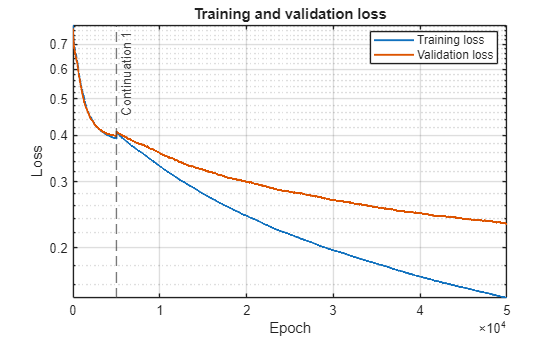

snn_plot_test_result(result);


=== Spiking Diagnostics: bc_test_classification ===
Samples: 8 | Neurons: 32000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 2.23721 Hz | median 2.08333 Hz | 95th percentile 5 Hz
Active neurons: 31366 / 32000 (98.02%)
Silent neurons: 634 / 32000 (1.98%)
Mean population rate by sample: 2.23721 Hz/neuron
Mean active neurons by sample: 36.32% | silent 63.68%
Total within-sample ISIs counted: 78837
Median per-neuron mean inverse-ISI rate: 9.83212 Hz


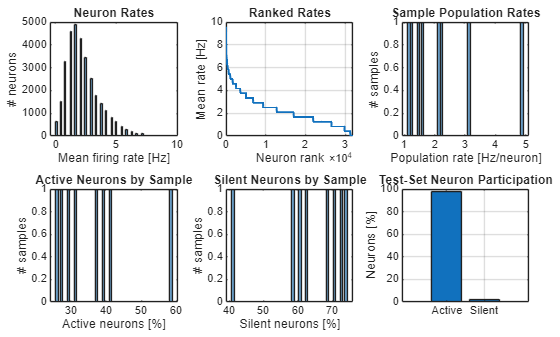

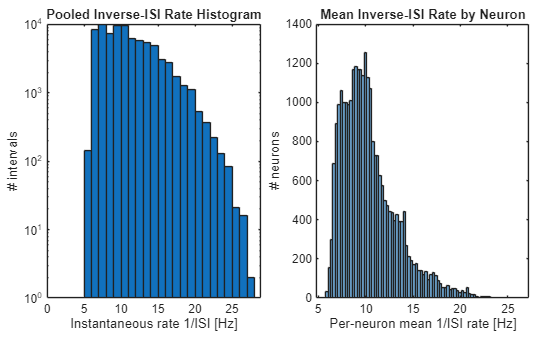

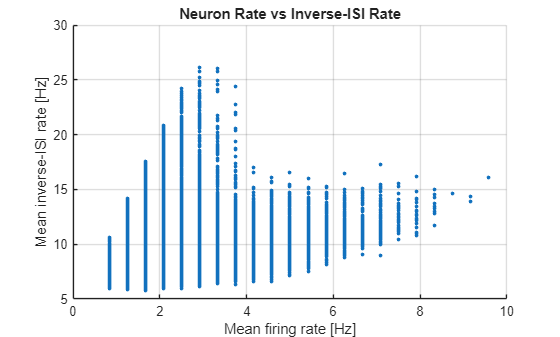

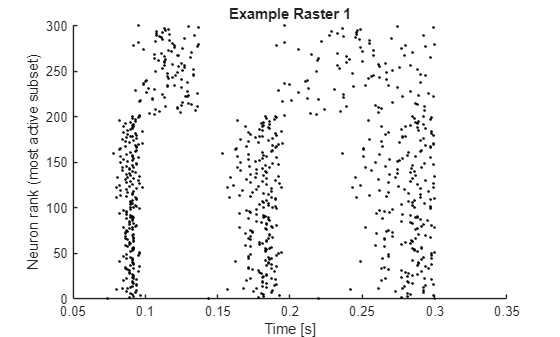

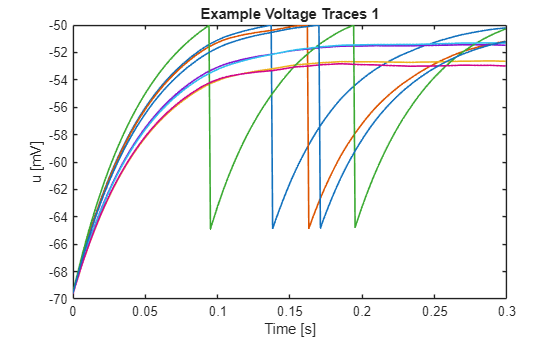

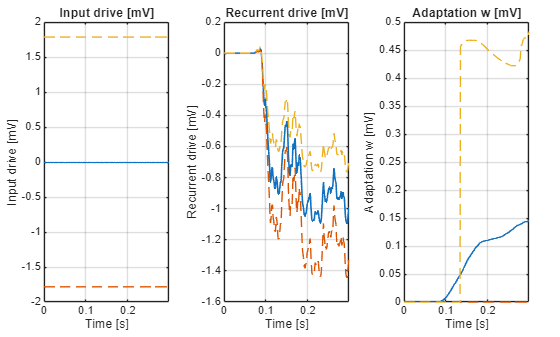

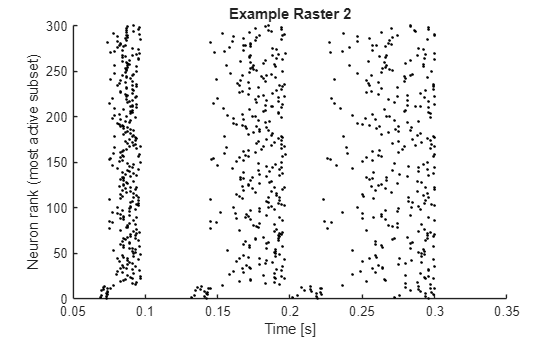

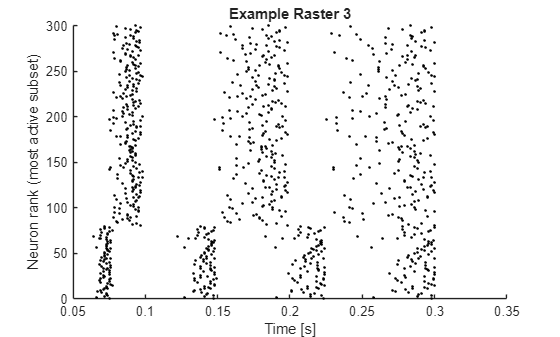

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_static', 'classification', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 98.02%% (31366/32000); silent neurons: 1.98%% (634/32000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 36.32%%; silent neurons: 63.68%%.


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

      loss: 0.2364
    metric: 93.9130
     count: 115
         Z: [2×115 single]
         Y: [2×115 single]

